Given $f=220\;\mathrm{GHz},D_f =3\ldotp 6\;\lambda_{0\;} ,D_{r\;} =130\;\lambda_0 \;\mathrm{and}\;f_# =1\ldotp 8\ldotp$

1.1 Calculate the GO electric field on the equivalent FO sphere of this geometry.

%% Initialize parameters
clc; clear; close all;

freq = 220e9;
lambda_0 = 3e8 / freq;
k_0 = 2 * pi / lambda_0;

E_0_PW = 1;

f_num = 1.8;
D_r = 130 * lambda_0;
D_f = 3.6 * lambda_0;

F = D_r * f_num;

R = F;

th_i = 0;
ph_i = 0;

One assumption was made in the simulation process. We conder the f-number is approximately $\frac{R}{D_r }$. The GO electric field can be found in the figure below. We can observe that the strength of the field on FO is fairly close to a constant as the difference between minmum and maximum is only differed by 0.16 dB. 

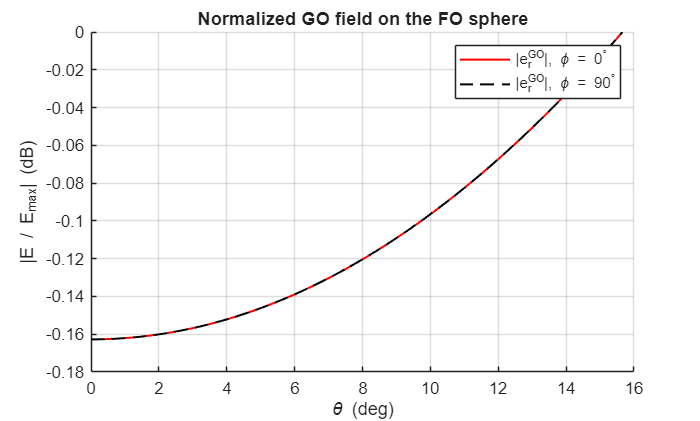

theta = linspace(0, pi/2, 501);
phi = linspace(0, 2*pi, 501);

[TH, PH] = meshgrid(theta, phi);

[V_GO_th, V_GO_ph] = GOField(TH, PH, th_i, ph_i, F, D_r);

e_r_GO_th =  V_GO_th .* exp(1j * k_0 * R) ./ R;
e_r_GO_ph =  V_GO_ph .* exp(1j * k_0 * R) ./ R;

e_r_GO_1 = sqrt(abs(V_GO_th(1, :)).^2 + abs(V_GO_ph(1, :)).^2);
e_r_GO_2 = sqrt(abs(V_GO_ph(end, :)).^2 + abs(V_GO_th(end, :)).^2);

figure
hold on
grid on
plot(rad2deg(theta), 20 * log10(e_r_GO_1 / max(e_r_GO_1)), 'r', 'LineWidth', 1.2)
plot(rad2deg(theta), 20 * log10(e_r_GO_2 / max(e_r_GO_2)), 'k--', 'LineWidth', 1.2)

xlabel('\theta (deg)')
ylabel('|E / E_{max}| (dB)')
title('Normalized GO field on the FO sphere')
legend('|e^{GO}_{r}|, \phi = 0^\circ', ...
           '|e^{GO}_{r}|, \phi = 90^\circ');

1.2  Evaluate the electric far field of the circular feed over the same FO sphere.

The required plot can be found below. We can oberved that the product of GO and far field is the highest around 0 - 2.5 degree, it suggest that the system might have a higher gain around this region. 

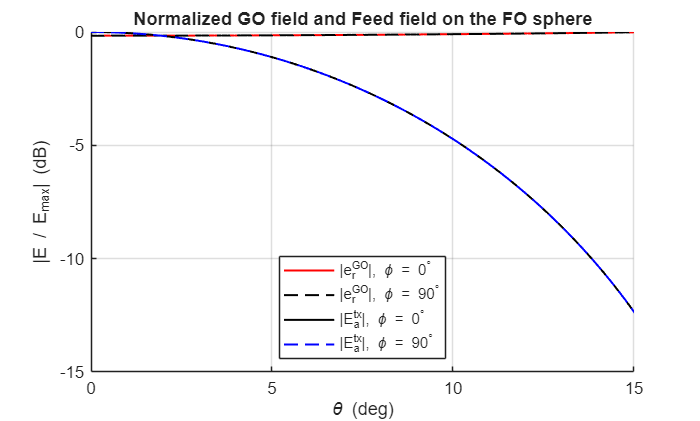

[V_a_th, V_a_ph, P_rad] = FeedField(TH, PH, D_f, k_0, R);
E_a_tx_th =  V_a_th .* exp(1j * k_0 * R) ./ R;
E_a_tx_ph =  V_a_ph .* exp(1j * k_0 * R) ./ R;
E_a_tx_1 = sqrt(abs(E_a_tx_th(1, :)).^2 + abs(E_a_tx_ph(1, :)).^2);
E_a_tx_2 = sqrt(abs(E_a_tx_ph(end, :)).^2 + abs(E_a_tx_th(end, :)).^2);

figure
hold on
grid on
plot(rad2deg(theta), 20 * log10(e_r_GO_1 / max(e_r_GO_1)), 'r', 'LineWidth', 1.2)
plot(rad2deg(theta), 20 * log10(e_r_GO_2 / max(e_r_GO_2)), 'k--', 'LineWidth', 1.2)
plot(rad2deg(theta), 20 * log10(E_a_tx_1 / max(E_a_tx_1)), 'k', 'LineWidth', 1.2)
plot(rad2deg(theta), 20 * log10(E_a_tx_2 / max(E_a_tx_2)), 'b--', 'LineWidth', 1.2)
xlabel('\theta (deg)')
ylabel('|E / E_{max}| (dB)')
title('Normalized GO field and Feed field on the FO sphere')
legend('|e^{GO}_{r}|, \phi = 0^\circ ', ...
       '|e^{GO}_{r}|, \phi = 90^\circ ', ...
       '|E_{a}^{tx}|, \phi = 0^\circ ', ...
       '|E_{a}^{tx}|, \phi = 90^\circ ', ...
       'Location', 'south')
xlim([0 15])
ylim([-15 0])

1.3  Using the analysis of antennas in reception for a generalized incidence, calculate the power received at the input terminals of the feed, assuming impedance matched condition. Provide the value of the aperture efficiency of the overall reflector antenna system. 

The received power and the aperture efficiency can be found below:

[P_rx, eta_ap] = RxPower(TH, PH, V_GO_th, V_GO_ph, V_a_th, V_a_ph, P_rad);
P_rx

P_rx = 2.3587e-05

eta_ap

eta_ap = 0.7206

Note that the value of the power and the aperture efficiency can change based on the number of sampling parameters defined for the meshgrid. 

1.4 Calculate the GO electric fields on the equivalent FO sphere of this geometry for each incident plane wave angle.

Due to the large number of data, the plots will not be plotted but all of the data can be calculated as follows:

theta_rx = linspace(0, pi/2, 501);
phi_rx = linspace(0, 2 * pi, 501);
[TH_rx, PH_rx] = meshgrid(theta_rx, phi_rx);

[V_a_th_rx, V_a_ph_rx, P_rad_rx] = FeedField(TH_rx, PH_rx, D_f, k_0, R);

%Same logic for ph but it will take too long to plot
th_i_sweep = linspace(-deg2rad(3), deg2rad(3), 301);

P_rx_cut = zeros(size(th_i_sweep));

for n = 1:length(th_i_sweep)
    th_i = th_i_sweep(n);
    ph_i = 0;
    [V_GO_th_rx, V_GO_ph_rx] = GOField(TH_rx, PH_rx, th_i, ph_i, F, D_r);
    [P_rx, ~] = RxPower(TH_rx, PH_rx, V_GO_th_rx, V_GO_ph_rx, V_a_th_rx, V_a_ph_rx, P_rad_rx);
    P_rx_cut(n) = P_rx;
end


1.5 Plot the power received by the reflector feed, in dBs and normalized, as a function of this incident angle. This plot represents the radiation pattern of the reflector antenna in reception mode. Compare this plot with the far field radiation pattern calculated using a transmission analysis of the same structure, as developed in MATLAB assignment 2.

The plot can be found below:

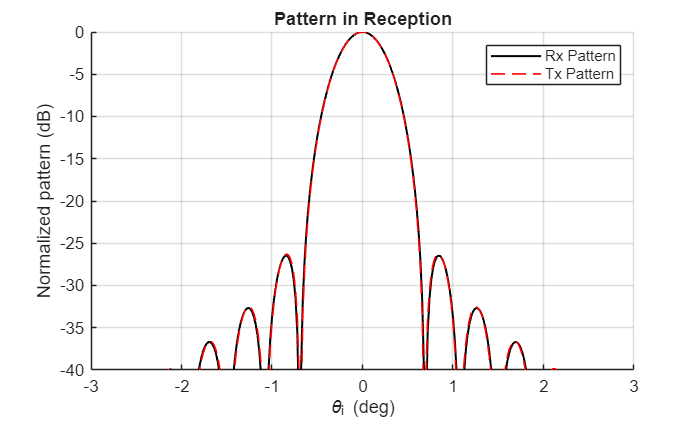

figure
grid on
hold on

plot(rad2deg(th_i_sweep), 10 * log10(P_rx_cut / max(P_rx_cut)), 'k', 'LineWidth', 1.2)
xlabel('\theta_i (deg)')
ylabel('Normalized pattern (dB)')
title('Pattern in Reception')
xlim([-3 3])
ylim([-40 0])


%%Pattern in transmission.

% constants
zeta0 = 120 * pi;
a    = D_f / 2;
J_f  = 1;
k0   = k_0;

f_focal = F;
f_hash = f_num;
D       = f_focal/f_hash;
th0 = 2 * acot(4 * f_hash);

% Angular grid
num_th = 401;
num_ph = 401;
theta_feed = linspace(eps, th0,  num_th); % Only use wave that will be reflected.
phi_feed   = linspace(eps, 2*pi,  num_ph);
[TH_feed, PH_feed] = meshgrid(theta_feed, phi_feed);

% Feed distance 
r_feed = 1; 
r_feed = r_feed .* ones(size(TH_feed));

% J_FT 
x = k0*a*sin(TH_feed);
J_FT = 2*pi*a^2 .* besselj(1, x) ./ x;  

% Common prefactor
pref = (-2*1j*k0*zeta0*J_f) .* J_FT .* exp(-1j*k0*r_feed) ./ (4*pi*r_feed);

% Spherical components 
E_theta = pref .* (cos(TH_feed) .* sin(PH_feed));
E_phi   = pref .* (cos(PH_feed));

% Change to cylindrical coordinates 
RHO_p = 2 .* f_focal .* tan(TH_feed ./ 2);
PH_p = PH_feed;

Ea_rho = -E_theta .* exp(-1j*k_0*2*f_focal).*cos(TH_feed/2).^2/f_focal;
Ea_phi = -E_phi .* exp(-1j*k_0*2*f_focal).*cos(TH_feed/2).^2/f_focal;

Ea_x = Ea_rho.*cos(PH_p) - Ea_phi.*sin(PH_p);
Ea_y = Ea_rho.*sin(PH_p) + Ea_phi.*cos(PH_p);

E_a = zeros([size(Ea_x), 3]);
E_a(:, :, 1) = Ea_x;
E_a(:, :, 2) = Ea_y;

n = zeros([size(TH_feed), 3]); 
n(:,:,3) = ones(size(TH_feed));

J_s = 1/zeta0 * cross(n, cross(n, E_a, 3), 3);
Js_x = 2 * J_s(:,:,1);
Js_y = 2 * J_s(:,:,2);

%Far field grid
R_ff = 10;
ph_ff = [0 pi/2];
th_ff = linspace(-deg2rad(3), deg2rad(3), 301);

Eth = zeros(length(ph_ff), length(th_ff));
Eph = zeros(length(ph_ff), length(th_ff));

dth = (pi/2)/(num_th-1);
dphi = (2*pi)/(num_ph-1);
drho = 2 .* f_focal .* tan(dth ./ 2);

for ii = 1:length(th_ff)
    for jj = 1:length(ph_ff)
        
        th  = th_ff(ii);
        ph  = ph_ff(jj);
        
        kx = k_0*sin(th)*cos(ph);
        ky = k_0*sin(th)*sin(ph);
        kz = k_0*cos(th);
        
        phase = exp(1j*(kx*RHO_p.*cos(PH_p) + ky*RHO_p.*sin(PH_p)));
        
        J_FT_x = sum(sum(Js_x .* phase .* RHO_p)) * drho * dphi;
        J_FT_y = sum(sum(Js_y .* phase .* RHO_p)) * drho * dphi;
        
        GF = EJ_SGF(zeta0, k_0, kx, ky);
        Gxx = GF(:,:,1,1); Gyx = GF(:,:,2,1); Gzx = GF(:,:,3,1);
        Gxy = GF(:,:,1,2); Gyy = GF(:,:,2,2); Gzy = GF(:,:,3,2);
        
        % Far field contributions
        [Eth_x, Eph_x] = farfield(k_0, R_ff, th, ph, kz, Gxx, Gyx, Gzx, J_FT_x);
        [Eth_y, Eph_y] = farfield(k_0, R_ff, th, ph, kz, Gxy, Gyy, Gzy, J_FT_y);
        
        Eth(jj, ii) = Eth_x + Eth_y;
        Eph(jj, ii) = Eph_x + Eph_y;
      
    end
end

% Total field
E_ff = sqrt(abs(Eth).^2 + abs(Eph).^2);
E_ff_max = max(max(20*log10(abs(E_ff))));

[~, idx_phi_0]  = min(abs(ph_ff - 0));

plot(rad2deg(th_ff), 20*log10(abs(E_ff(idx_phi_0,:)))  - E_ff_max, 'r--', 'LineWidth',1)

legend('Rx Pattern', 'Tx Pattern'); 

As we can see in the plot, Rx pattern and Tx pattern perfectly align with each other, which verifies our calculation in Rx.

1.6 Compare the aperture efficiencies, directivities and gains obtained using both Tx and Rx analysis.

The maximum directivity is shape dependent and it follows the following formula:

$D_{\mathrm{ir}}^{\max } =\frac{\pi^2 D_r^2 \;}{\lambda_0^2 }$.

Since Tx and Rx share the same structure, the maximum directivity would be the same.

Now we compare the aperature efficicency of Rx and Tx:


%% Constants 
f = freq;
c0 = 3e8;
lambda_0 = c0 / f;
k0 = 2*pi / lambda_0;
k  = k0;

zeta0 = 120*pi;

a   = D_f/2;
J_f = 1;

f_focal = F;             
num_th  = 501;
num_ph  = 501;

%% Choose one f_hash
f_hash = f_num;   % change this value
D   = D_r;
th0 = 2 * acot(4 * f_hash);

%% Phi grids 
phi_taper = linspace(eps, 2*pi, num_ph);
phi_spill = linspace(eps, 2*pi, num_ph);

%% TAPER EFFICIENCY
theta_taper = linspace(eps, th0, num_th);
[TH1, PH1] = meshgrid(theta_taper, phi_taper);

r1 = 1;
x1 = k0*a*sin(TH1);
J_FT1 = 2*pi*a^2 .* besselj(1, x1) ./ x1;
pref1 = (-2*1j*k0*zeta0*J_f) .* J_FT1 .* exp(-1j*k0*r1) ./ (4*pi*r1);

E_theta1 = pref1 .* (cos(TH1) .* sin(PH1));
E_phi1   = pref1 .* (cos(PH1));

% Cylindrical mapping 
RHO_p = 2 .* f_focal .* tan(TH1 ./ 2);
PH_p  = PH1;

phase_ap = exp(-1j*k*2*f_focal) .* (cos(TH1/2).^2) / f_focal;

Ea_rho = -E_theta1 .* phase_ap;
Ea_phi = -E_phi1   .* phase_ap;

Ea_x = Ea_rho.*cos(PH_p) - Ea_phi.*sin(PH_p);
Ea_y = Ea_rho.*sin(PH_p) + Ea_phi.*cos(PH_p);

E_a = zeros([size(Ea_x), 3]);   
E_a(:,:,1) = Ea_x;
E_a(:,:,2) = Ea_y;

dth  = th0/(num_th-1);
dphi = (2*pi)/(num_ph-1);
drho = 2 .* f_focal .* tan(dth/2);

int_vec = sum(sum(E_a .* RHO_p, 1), 2) * drho * dphi;  
numerator_sq = abs(sum(int_vec, 3)).^2;

integrand_den = sum(abs(E_a).^2, 3);
denominator   = sum(sum(integrand_den .* RHO_p)) * drho * dphi;

A = pi * (D/2)^2;
eta_taper = (1/A) * numerator_sq / denominator;

%% SPILLOVER EFFICIENCY
theta_spill = linspace(eps, pi/2, num_th);
[TH2, PH2] = meshgrid(theta_spill, phi_spill);

r2 = 1;
x2 = k0*a*sin(TH2);
J_FT2 = 2*pi*a^2 .* besselj(1, x2) ./ x2;
pref2 = (-2*1j*k0*zeta0*J_f) .* J_FT2 .* exp(-1j*k0*r2) ./ (4*pi*r2);

E_theta2 = pref2 .* (cos(TH2) .* sin(PH2));
E_phi2   = pref2 .* (cos(PH2));

E_mag  = sqrt(abs(E_theta2).^2 + abs(E_phi2).^2);
U_feed = (1/(2*zeta0)) .* (abs(E_mag).^2) .* sin(TH2);

U_cap = U_feed;
U_cap(TH2 > th0) = 0;

dth_feed = (pi/2)/(num_th-1);
dph_feed = (2*pi)/(num_ph-1);

eta_spill = (sum(U_cap,'all')*dth_feed*dph_feed) / (sum(U_feed,'all')*dth_feed*dph_feed);

%% Aperture efficiency
eta_ap = real(eta_taper * eta_spill);

disp(['eta_ap    = ', num2str(eta_ap)])

eta_ap    = 0.71855


Here we can find that the aperture efficiency of Tx is 71.86% while the aperture efficiency is 72.06%. They are fairly close and the mismatch is probably due to the rounding error along the calculation. 

And we know the gain can be directly dervied from max directivity and aperture efficiency:

$G=D_{\mathrm{ir}}^{\max } \eta {\;}_{\mathrm{ap}}$.

Since Tx and Rx have the exact maxnimum directivity and close aperture efficiency, their gain would also be similar. 

### Part 2: Feed displaced in the focal plane of the parabolic reflector

2.1 Consider $d_{x\;} =D_{f\;} =3\ldotp 6\;\lambda_0 \ldotp \;$Plot the pattern in reception of this displaced field and evaluate the aperture efficiency. Compare them to the feed in the center. What is the pointing direction in the displaced case? What differences do you notice between the two beams?

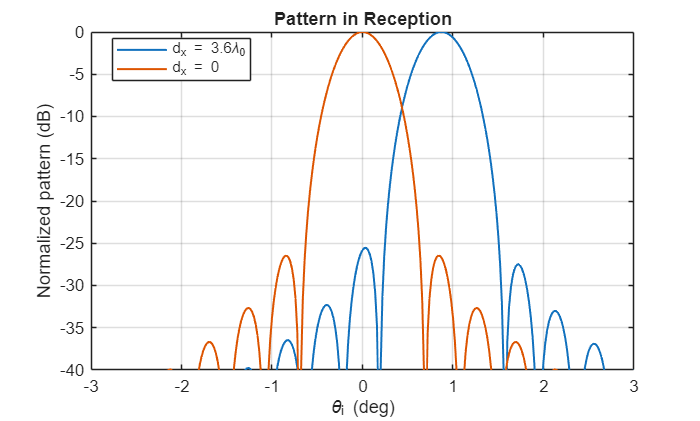

theta_rx = linspace(0, pi/2, 501);
phi_rx   = linspace(0, 2*pi, 501);
[TH_rx, PH_rx] = meshgrid(theta_rx, phi_rx);

th_i_sweep = linspace(-deg2rad(3), deg2rad(3), 301);

dx_vals = [3.6*lambda_0, 0];
P_rx_cut_all = zeros(length(dx_vals), length(th_i_sweep));

for m = 1:length(dx_vals)
    d_x = dx_vals(m);

    [V_a_th_rx, V_a_ph_rx, P_rad_rx] = FeedField(TH_rx, PH_rx, D_f, k_0, R, d_x);

    for n = 1:length(th_i_sweep)
        th_i = th_i_sweep(n);
        ph_i = 0;

        [V_GO_th_rx, V_GO_ph_rx] = GOField(TH_rx, PH_rx, th_i, ph_i, F, D_r);
        [P_rx, ~] = RxPower(TH_rx, PH_rx, V_GO_th_rx, V_GO_ph_rx, V_a_th_rx, V_a_ph_rx, P_rad_rx);

        P_rx_cut_all(m, n) = P_rx;
    end
end

figure
plot(rad2deg(th_i_sweep), 10*log10(P_rx_cut_all(1,:) / max(P_rx_cut_all(1,:))), ...
    'LineWidth', 1.2)
hold on
plot(rad2deg(th_i_sweep), 10*log10(P_rx_cut_all(2,:) / max(P_rx_cut_all(2,:))), ...
    'LineWidth', 1.2)

grid on
xlabel('\theta_i (deg)')
ylabel('Normalized pattern (dB)')
title('Pattern in Reception')
legend('d_x = 3.6\lambda_0', 'd_x = 0', 'Location', 'best')
xlim([-3 3])
ylim([-40 0])

%Resulting efficiency
th_i = deg2rad(0.87);
ph_i = 0;
theta = linspace(0, pi/2, 501);
phi = linspace(0, 2*pi, 501);

[TH, PH] = meshgrid(theta, phi);

[V_GO_th, V_GO_ph] = GOField(TH, PH, th_i, ph_i, F, D_r);

d_x = 2*lambda_0*f_num;
[V_a_th, V_a_ph, P_rad] = FeedField(TH, PH, D_f, k_0, R, d_x);


[~, eta_ap] = RxPower(TH, PH, V_GO_th, V_GO_ph, V_a_th, V_a_ph, P_rad);

eta_ap

eta_ap = 0.7204

The plot can be found above, the aperture efficiency reaches maxinimum when $\theta_{i\;} =0\ldotp {87}^o$, and this direciton is the pointing direciton.  The resulting efficiency is same as the aperture efficiency of the feed in the center case. It implies that a shift in current density will result a shift in reception pattern and the aperture efficiency remains the same. 

2.2

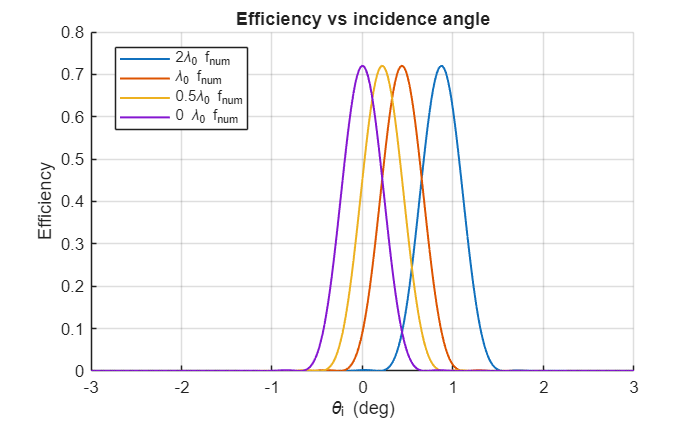

theta_rx = linspace(0, pi/2, 501);
phi_rx   = linspace(0, 2*pi, 501);
[TH_rx, PH_rx] = meshgrid(theta_rx, phi_rx);

th_i_sweep = linspace(-deg2rad(3), deg2rad(3), 301);

% From the assignment:
% d_x = 2*lambda_0*f_num, lambda_0*f_num, 0.5*lambda_0*f_num
dx_vals   = [2, 1, 0.5, 0] * lambda_0 * f_num;
dx_labels = {'2\lambda_0 f_{num}', '\lambda_0 f_{num}', '0.5\lambda_0 f_{num}', '0 \lambda_0 f_{num}'};

P_rx_cut_all = zeros(length(dx_vals), length(th_i_sweep));
eta_cut_all  = zeros(length(dx_vals), length(th_i_sweep));

for m = 1:length(dx_vals)
    d_x = dx_vals(m);

    [V_a_th_rx, V_a_ph_rx, P_rad_rx] = FeedField(TH_rx, PH_rx, D_f, k_0, R, d_x);

    for n = 1:length(th_i_sweep)
        th_i = th_i_sweep(n);
        ph_i = 0;

        [V_GO_th_rx, V_GO_ph_rx] = GOField(TH_rx, PH_rx, th_i, ph_i, F, D_r);
        [P_rx, eta_rx] = RxPower(TH_rx, PH_rx, V_GO_th_rx, V_GO_ph_rx, ...
                                 V_a_th_rx, V_a_ph_rx, P_rad_rx);

        P_rx_cut_all(m, n) = P_rx;
        eta_cut_all(m, n)  = eta_rx;
    end

end

%% Efficiency pattern
figure
hold on
for m = 1:length(dx_vals)
    plot(rad2deg(th_i_sweep), eta_cut_all(m,:), ...
         'LineWidth', 1.2, 'DisplayName', dx_labels{m});
end
grid on
xlabel('\theta_i (deg)')
ylabel('Efficiency')
title('Efficiency vs incidence angle')
legend('Location', 'best')
xlim([-3 3])

As shown in the figure above, the aperature efficiency is affected by the incidence angle. At the pointing direction, the efficiency would be maxinimum for each displacement.  

%% Power pattern plot
figure
hold on
for m = 1:length(dx_vals)
    plot(rad2deg(th_i_sweep), ...
         10*log10(P_rx_cut_all(m,:) / max(P_rx_cut_all(m,:))), ...
         'LineWidth', 1.2, 'DisplayName', dx_labels{m});
end
grid on
xlabel('\theta_i (deg)')
ylabel('Normalized pattern (dB)')
title('Power pattern for different feed displacements')
legend('Location', 'best')
xlim([-3 3])
ylim([-40 0])
lambda_0F_numLine = findobj(gcf, "DisplayName", "0 \lambda_0 f_{num}");

lambda_0F_numLine =   Line (0 \lambda_0 f_{num}) with properties:

              Color: [0.5210 0.0860 0.8190]
          LineStyle: '-'
          LineWidth: 1.2000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-3.0000 -2.9800 -2.9600 -2.9400 -2.9200 -2.9000 -2.8800 -2.8600 -2.8400 -2.8200 -2.8000 -2.7800 -2.7600 -2.7400 -2.7200 -2.7000 -2.6800 -2.6600 -2.6400 -2.6200 -2.6000 -2.5800 -2.5600 -2.5400 -2.5200 -2.5000 … ] (1×301 double)
              YData: [-44.5405 -44.6906 -45.0335 -45.5900 -46.3951 -47.5074 -49.0277 -51.1471 -54.2893 -59.7486 -80.1170 -61.0641 -54.6275 -51.0171 -48.5563 -46.7448 -45.3659 -44.3075 -43.5052 -42.9205 -42.5303 -42.3221 -42.2916 … ] (1×301 double)

  Show 

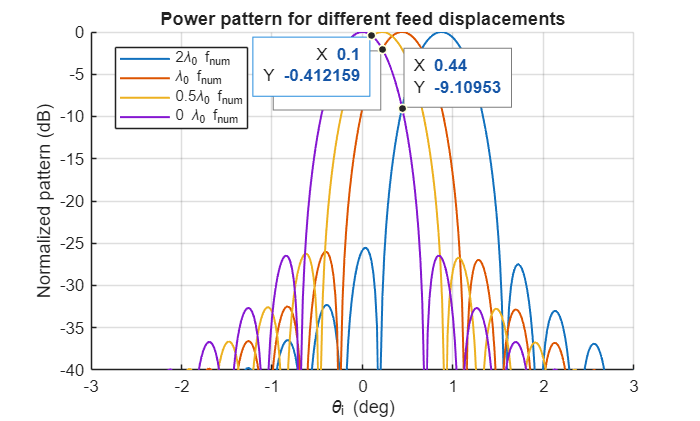

datatip(lambda_0F_numLine,0.44,-9.11);
datatip(lambda_0F_numLine,0.22,-2.042,"Location","southwest");
datatip(lambda_0F_numLine,0.1,-0.4122,"Location","southwest");

The beam crossing levels in dB for each of the three sampling scenarios above are -0.4dB, -2.0 dB, and -9.1 dB for  ${0\ldotp 5\lambda }_0 f_#$, $\lambda_0 f_#$, ${2\lambda }_0 f_#$, respectively. They are all 1 dB higher than expected. The discrepancies could come from scan loss of QO system and the f-number we have. 